## Key Conceps about Images

### Image function

A mathematical function g(x,y) that represents the ligthing intensity of each pixel of an image, which has finite values and a finite size.

where:

- x > 0 and y > 0

### Digital image

A function f(x,y) that assings the ligthing intensity of each pixel of an image.

where:

- x and y are ints

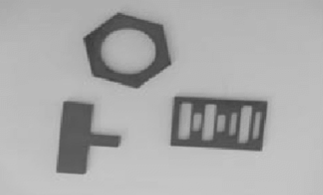   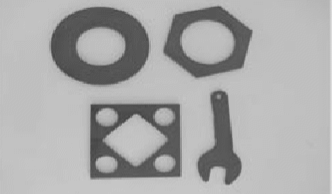   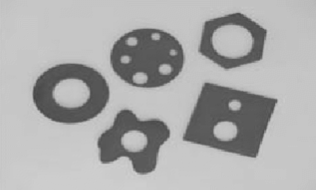

### Binary image

A function b(x,y) of an image f(x,y) which was quantized into two levels of lightning intensity, 0 and 1.

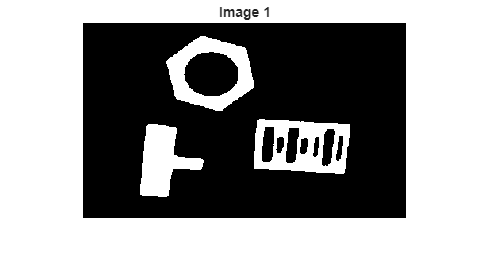

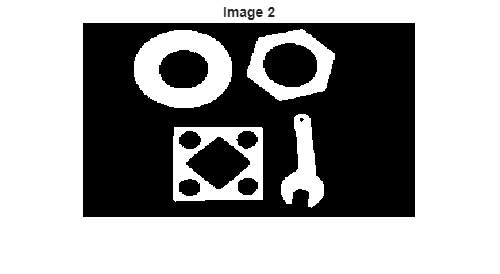

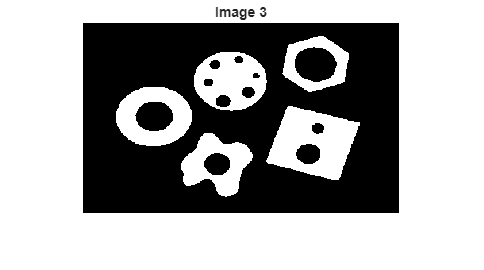

for i = 1:3
    img = sprintf('images\\Cap4 img%d.png', i);
    f = imread(img);
    [n, m, c] = size(f);
    niveles = [1 256];
    g = zeros(n, m);

    for y = 1:n
        for x = 1:m
            if f(y,x) <= 128
                g(y,x) = 1;
            else
                g(y,x) = 0;
            end
        end
    end
    figure;
    imshow(g);
    title(sprintf('Image %d', i));
end